%% Making Surface Plots From Scatter Data
% How do you turn a collection of XYZ triplets into a surface plot? This is
% the most frequently asked 3D plotting question that I got when I was in
% Tech Support.


## Load the data

f = load("table1.mat")

f = struct with fields:
    teslametric1S1: [107×3 table]


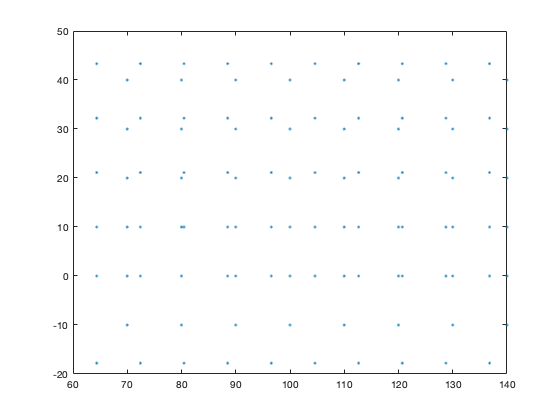


file = f.teslametric1S1;

x = file.Speedkph;
y = file.TemperatureC;
z = file.MileageWhkm;
%%
% The problem is that the da ta is made up of individual (x,y,z)
% measurements. It isn't laid out on a rectilinear grid, which is what the
% SURF command expects. A simple plot command isn't very useful.


%% Little triangles
% The solution is to use Delaunay triangulation. Let's look at some
% info about the "tri" variable.

tri = delaunay(x,y);
plot(x,y,'.')


%%
% How many triangles are there?

[r,c] = size(tri);
disp(r)

   182



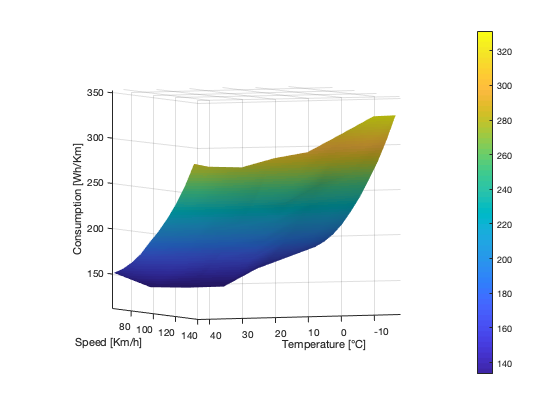


%% Plot it with TRISURF

trisurf(tri, x, y, z);
axis vis3d

%% Clean it up

axis on
xlabel("Speed [Km/h]")
ylabel("Temperature [°C]")
zlabel("Consumption [Wh/Km]")

light('Position',[-50 -15 29])
set(gca,'CameraPosition',[208 -50 7687])
lighting phong
shading interp
colorbar EastOutside

view([-67 -3])


%% Plot it with TRISURF

h = trisurf(tri, x, y, z);
axis vis3d

%% Clean it up

axis on
xlabel("Speed [Km/h]")
ylabel("Temperature [°C]")
zlabel("Consumption [Wh/Km]")

l = light('Position',[-50 -15 29])

l =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [-50 -15 29]
     Visible: 'on'

  Show all properties


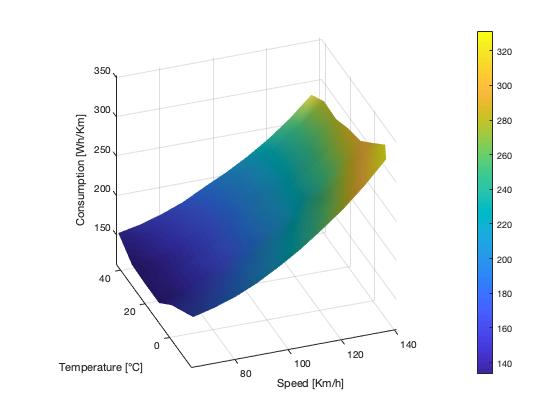


set(gca,'CameraPosition',[208 -50 7687])
lighting phong
shading interp
colorbar EastOutside

view([-20, 30])